# Lesson 4

Written by Brenda So and Cory Nezin, modified by Guy Bar Yosef.

# Objective

After this class, you should be able to:

- Understand basic debugging in MATLAB

- Know how to use control sequences (for, if, else, while, try and catch blocks)

- Understand matrix operations such as reshape and meshgrid

- Know how to input and output files in MATLAB

# Control Sequences

Similar to C, MATALB has control sequence commands. Last class we explored for loops and the difference between for loops and vectorization. Even though vectorization is more computationally efficient than loops, sometimes for loops and other control sequences are necessary, such as to perform simulations. 

Assuming that everyone has an understanding of control sequences, we will not delve too deep into the discussion of their mechanics but rather show you the semantics of the statements.

# For Loops

total = 0;
for i = 1:10
    total = total + i;
end
total

total = 55

# If...Else Statements

vgpa = 1.76;
wgpa = 2.52;
xgpa = 3.55;
ygpa = 3.76;
zgpa = 3.83;
gpa = zgpa;
if gpa < 2
    fprintf('You are in DANGER!!!\n')
elseif gpa >= 2 && gpa < 3.5
    fprintf('You are safe.\n')
elseif gpa >= 3.5 && gpa < 3.7
    fprintf('Cum Laude\n')
elseif gpa >= 3.7 && gpa < 3.8
    fprintf('Magna Cum Laude\n')
elseif gpa >= 3.8 && gpa < 4
    fprintf('Summa Cum Laude\n')
end

Summa Cum Laude


# While Loop

total = 0;
i = 0;
while i <= 10
    total = total +i;
    i = i+1;
end
total

total = 55

# Try and catch blocks

Try and catch allows you to "catch" errors and display error statements. They can also help if you don't know whether a certain statement would run correctly or not and your program depends on that certain line of code. Catching the error can allow you to gaurantee the rest of the program works correctly. 

try
    a = [1 2; 3 4];
    b = [1 2 3 4];
    c = a*b
catch err
    fprintf('You are trying to do something which is not allowed');
    % You can check the documentation for more things you can do with 
    % try-catch blocks, including information you can get from the error.
end

You are trying to do something which is not allowed

# Matrix Operations

We will quickly cover some common matrix operations which are often tricky to grasp at first.

## Reshape

When you are reshaping an array / matrix, the first dimension is filled first, and then the second dimension and so on...

M = 1:100;
N1 = reshape(M,2,2,[]);    % It would create a 2*2*25 matrix
N2 = reshape(M,[2,2,25]);  % Same as N1
N2(:,:,25)                 % Gives you 97,98,99,100

ans =     97    99
    98   100


N2(:,1,25)                 % Gives you 97 and 98

ans =     97
    98


## Meshgrid

Meshgrid is quite hard to understand. Think of it as a way to replicate arrays. Take the following example:

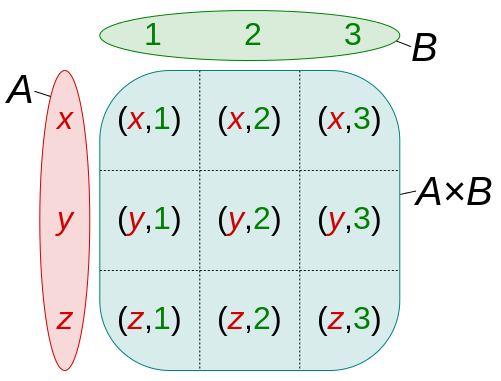

a = 1:3

a =      1     2     3


b = 1:5

b =      1     2     3     4     5


[A,B] = meshgrid(a,b) 

A =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


B =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


You have created two arrays A and B. Note that in A, the vector a is copied row-wise, while the vector b is transposed and copied column-wise. This is useful because when you lay one above the other, you essentially create a CARTESIAN PRODUCT and it is useful when we need to plot a 3D graph: https://en.wikipedia.org/wiki/Cartesian_product 

Here is a more complicated example to show you when meshgrid is useful

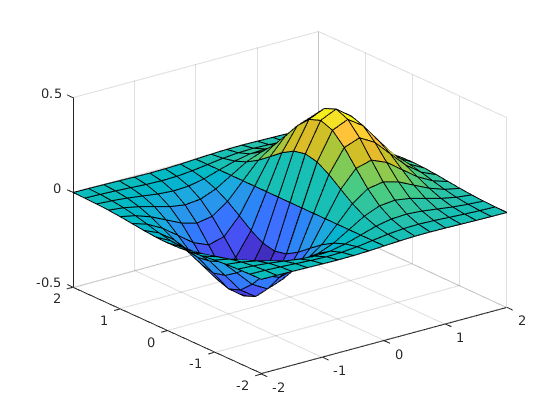

a1 = -2:0.25:2;
[A1,B1] = meshgrid(a1);
% Here we plot the surface of f(x) = x*exp^(x.^2+y.^2)
F = A1.*exp(-A1.^2-B1.^2);
surf(A1,B1,F)

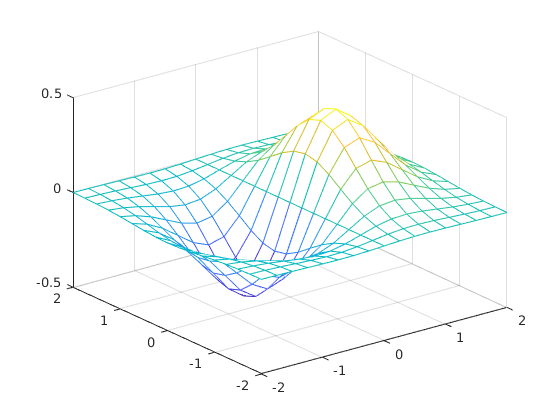

mesh(A1,B1,F)

# File I/O

Very often, you would need to process files that are not already in MATLAB. For instance, if you have a comma separated value file (csv), you would need to find a systematic way to load all your data into MATLAB. Moreover, you might also want to export figures and data from MATLAB, hence the need to learn file I/O. We are only convering a subset of file I/O in this section, more information can be found here: [https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html](https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html) .

## Importing data

mypic = load('brenda_so.mat');                      % Import a .mat file
% can open with image(brenda_so.mypic)

[y, Fs] = audioread('hallelujah.wav');              % Import an audio
% can play with sound(y, Fs)

fileID = fopen('grades.txt');
C_text = textscan(fileID,'%s',4,'Delimiter','|')    % Import a textfile

C_text = 1×1 cell array
    {4×1 cell}


C_data0 = textscan(fileID,'%d %f %f %f')            % Import the data in the textfile  

C_data0 = 1×4 cell array
    {4×1 int32}    {4×1 double}    {4×1 double}    {4×1 double}


C_data0{1}

ans = 4×1 int32 column vector
   1
   2
   3
   4


Note that when importing a textfile, it returns an array of cells. 

## Exporting data

save('allData')                  % saves your whole workspace into a .mat file
audiowrite('mySong.wav',y,Fs)    % saves audio
fileID = fopen('myFile.txt','w');
fprintf(fileID,'1 Januar 2014, 20.2, 100.5 \n');
fprintf(fileID,'1 Februar 2014, 21.6, 102.7 \n');
fprintf(fileID,'1 März 2014, 20.7, 99.8 \n');
fclose(fileID);

# Lab

Write a function that takes in an N x 1 vector of standard deviations, $\sigma$, an M x 1 vector of means, $\mu$, and an P x 1 vector of evaluation points.  The function should then plot NxM Gaussian shapes characterized by $F_{i,j} \left(x\right)=\;\frac{1}{\sqrt{2\pi {\sigma^2 }_{ˆi} }}\exp \left(-\frac{{\left(x-u_j \right)}^2 }{2{\sigma_i }^2 }\right)$. (where i ranges from 1 to N and j ranges from 1 to M).  Basically, plot the equation for every combination of $\mu$and $\sigma$.  Add appropriate legend and axis labels.

- First, generate the Gaussian vectors.  This can be done without any loops using *ndgrid*.

- Create a new figure. Enumerate through all of the $\mu 's$and $\sigma 's$ using a double for loop.

- Within the loop, create a legend which identifies each curve by its standard deviation and mean.  For example if you want to add a label for a curve with standard deviation 3 and mean 2, write *legendString = ['\mu = ',num2str(2),' \sigma = ',num2str(3)];* and     *plot(x,yourCurveNameGoesHere,'DisplayName',legendString).* Make sure you *hold on*!

- Finally, give the figure a title, add some labels, and show the legend.

Here is an example of what your final product should look like: